# **DIP Project - Processing Fundus Images**

## **Generating Mask using Thresholding at level 0.1**

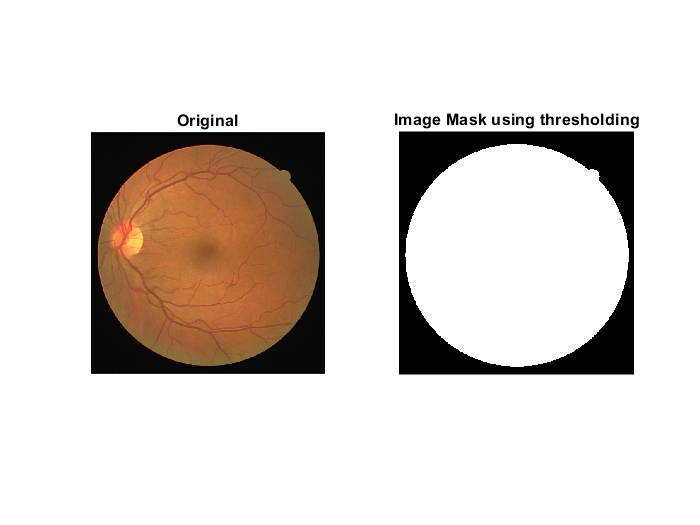

%Loading the orignal image
img=imread('fundus images jpeg/A (1).jpg');
imgbw=im2bw(img,0.1); %pixels greater than level 0.1 changed to white

subplot(1,2,1)
imshow(img)
title('Original')

subplot(1,2,2)
imshow(imgbw)
title('Image Mask using thresholding')

## Vessal Segmentation

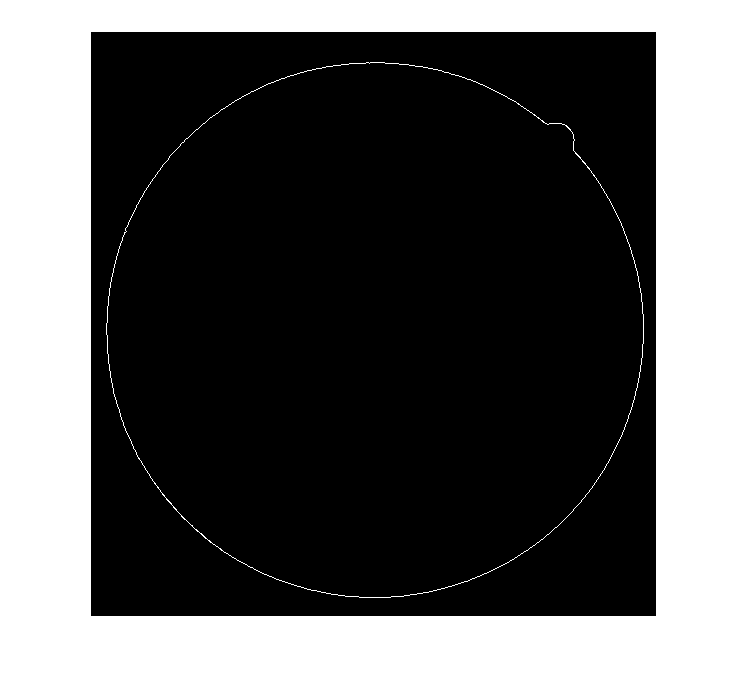

I = imread('fundus images jpeg/A (1).jpg');
gray=rgb2gray(I); %change to gray
I_binary=im2bw(gray,0.1); %thresholding
img1 = edge(I_binary,'sobel'); %edge detection of threshold image

figure, imshow(img1)

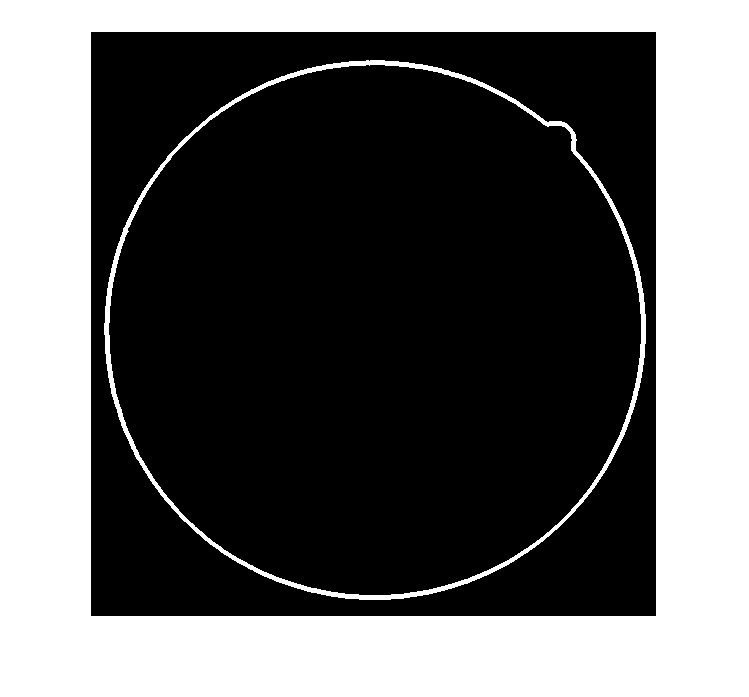


gray_adjust = imadjust(gray,[0.1 0.9],[]); %contrast stretching
se = strel('disk',2); 
img2 = edge(gray_adjust,'canny',0.15);
dilate = imdilate(img1,se); 

figure, imshow(dilate)

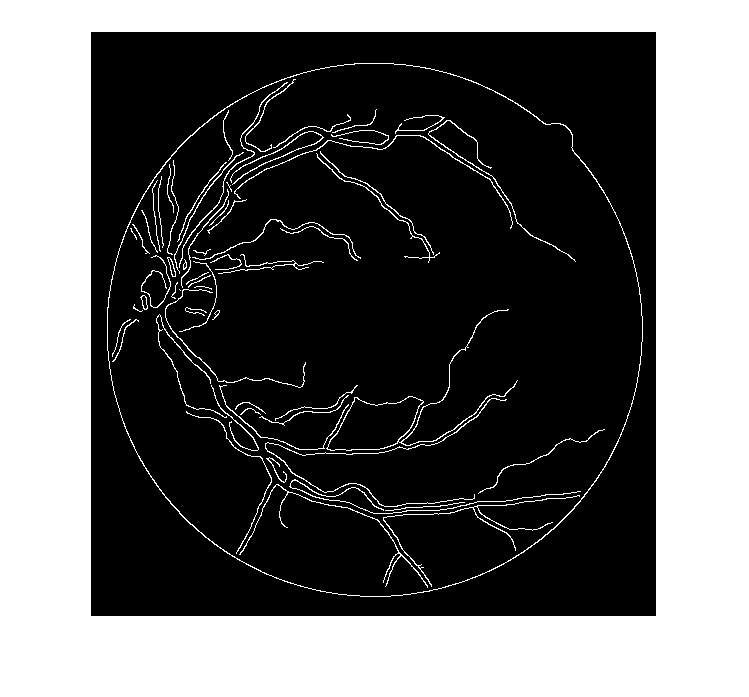


img3=img2-dilate;

figure, imshow(img2)

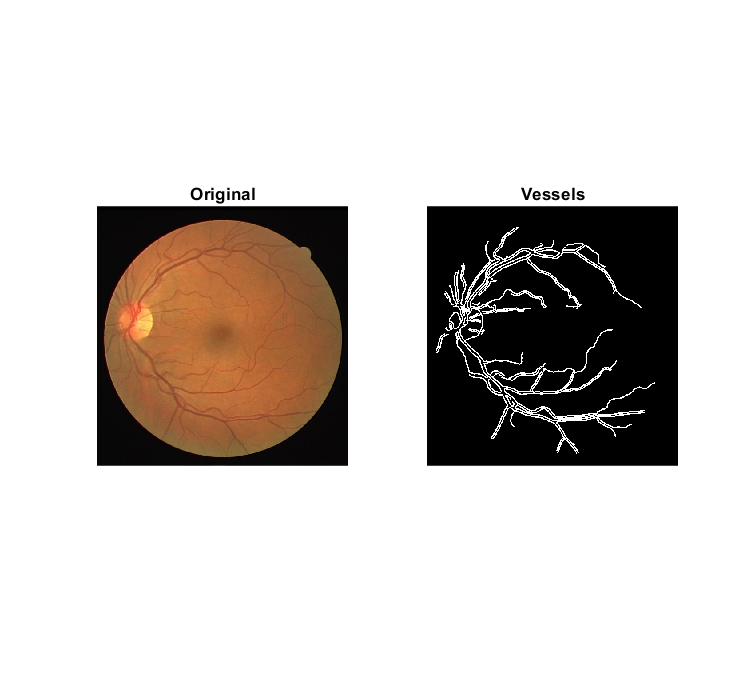


se = strel('disk',1);
img3=imdilate(img3,se);

subplot(1,2,1)
imshow(I)
title('Original')

subplot(1,2,2)
imshow(img3)
title('Vessels')

## Localization of the optic disk center

img=imread('fundus images jpeg/A (1).jpg');
img1=rgb2gray(img);
img1=im2double(img1);

[rows,cols]=size(img1);

% Power law transformation
for i=1:rows
    for j=1:cols
        temp=img1(i,j);
        newimg(i,j)=(temp^6.5);
    end
end

BW = im2bw(newimg, max(img1(:))/25);

se = strel('disk',2);
eroded = imerode(BW,se);

% imshowpair(img, eroded, 'montage')

C = corner(eroded);
figure,imshow(img)
hold on
%plot(C(:,1),C(:,2),'*');
centre=mean(C)

centre =    92.7143  258.4107


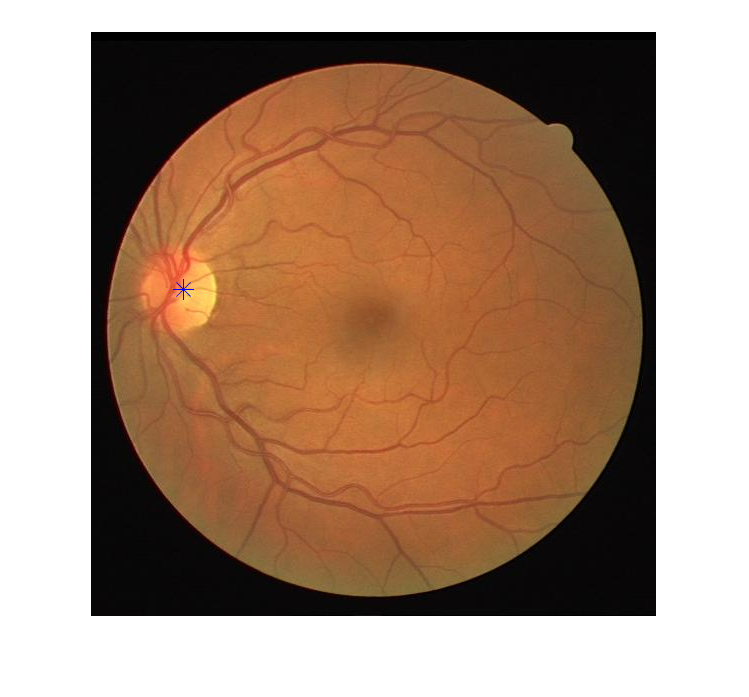

plot(centre(:,1),centre(:,2),'b*','MarkerSize',12);

## Boundary estimation of the optic disk

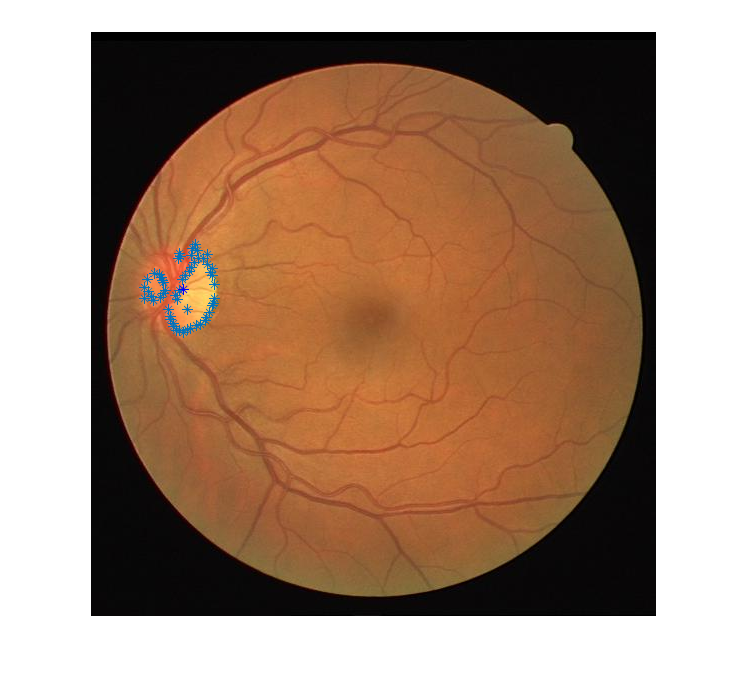

img=imread('fundus images jpeg/A (1).jpg');
img1=rgb2gray(img);
img1=im2double(img1);

[rows,cols]=size(img1);

% Power law transformation
for i=1:rows
    for j=1:cols
        temp=img1(i,j);
        newimg(i,j)=(temp^6.5);
    end
end

BW = im2bw(newimg, max(img1(:))/25);

se = strel('disk',2);
eroded = imerode(BW,se);

% imshowpair(img, eroded, 'montage')

C = corner(eroded);
figure,imshow(img)
hold on
plot(C(:,1),C(:,2),'*');
centre=mean(C);
plot(centre(:,1),centre(:,2),'b*');